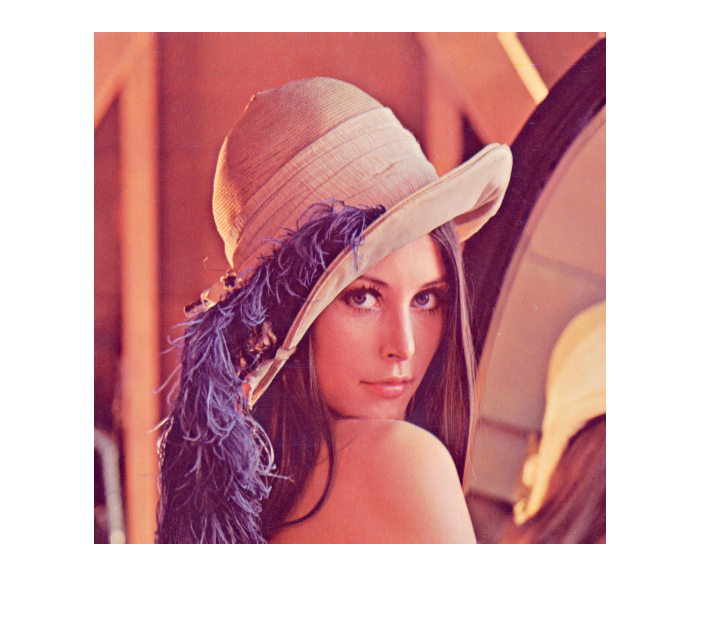

%% data preparation

path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\project_repo\MCoding_project\data\';
% path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\';
% path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\project_repo\MCoding_project\Data_Set\Images\';
A = imread(strcat(path,'lena.tiff'));
% A = imread(strcat(path, 'lena_full.jfif'));
imshow(A)

%% Try image with good ol' kmeans first
%reshape image stacking columns
k = 256;
A_r = reshape(A, [],3);
[idx, C] = kmeans(double(A_r), k);

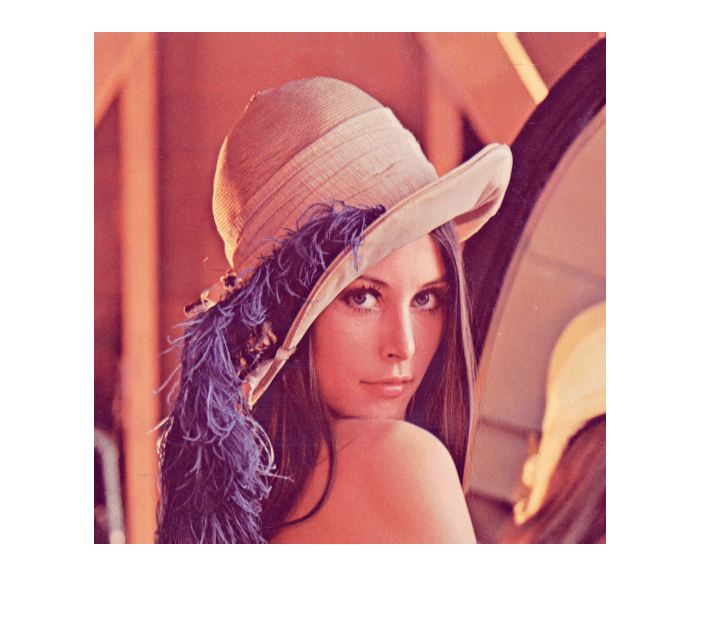

A_k3D = zeros(size(A_r));
C;
% bad implemented with cycles
A_k3D = zeros(size(A_r));
for p = 1:size(idx)
    for i = 1:k
        if idx(p)==i
            A_k3D(p,:) = C(i,:);
        end
    end
end
% % better implementation
% mapfrom = zeros(size(C));
% mapfrom(:,1) = 1:k;
% [sortfrom, sortidx] = sort(mapfrom);
% sortto = C(sortidx);
% A_k3D = zeros(size(A_r));
% A_k3D(:,1) = idx;
% 
% A_k3D = interp1(sortfrom, sortto, A_k3D);


A_k3D = uint8(reshape(A_k3D, size(A)));
imshow(A_k3D)


[d, dImg] = imageDistortion(A, A_k3D);

d = 0.0295

d

d = 0.0295

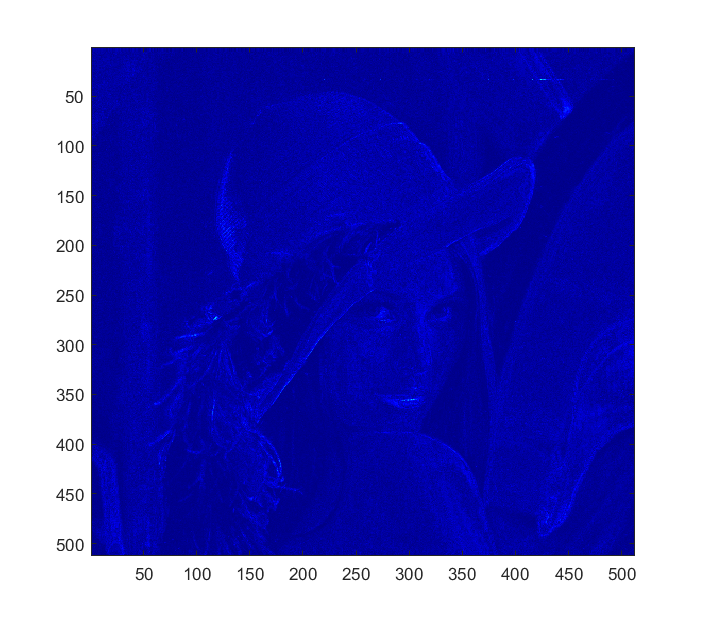


image(dImg)

%%implementing my vector quantization
% target R=8 bit/pixel
% at first we have 24 bit/pixel

%reshape image ready for clustering
A_r = double(reshape(A, [],3))./255;

%get initial rate of the image
% assuming intial is uint8 image range [0,255] values
r = size(A,3)*log2(256);

%we need to run the LBGSplit in a tree with eight levels

C = LBGSplitRecursive(A_r, 1);

debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base
debug base

eps = 0.0100

X1 =     0.5619    0.8593    0.2586
    0.3958    0.9742    0.8979
    0.3981    0.5708    0.5934
    0.5154    0.9969    0.5038
    0.6575    0.5535    0.6128
    0.9509    0.5155    0.8194
    0.7223    0.3307    0.5319
    0.8319    0.4918    0.4539
    0.0605    0.8877    0.9661
    0.3242    0.8266    0.7202


X2 =     0.4001    0.4300    0.2021
    0.1343    0.0710    0.4279
    0.0842    0.0646    0.6201
    0.1639    0.4362    0.6954
    0.3017    0.3945    0.3469
    0.0117    0.6135    0.5170
    0.0954    0.8862    0.1565
    0.6311    0.1908    0.6948
